%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                        Matlab Code 
%           Exact Solution for 1D Euler equations 
%               (Z.J. Wang, October 2021)
%
% Notes:
%   1.  flow == 1: subsonic
%       flow == 2: transonic with a shock wave after the throat
%   2. Domain size [xmin,xmax];
%   3. Uniform mesh is used
%
% Code by Dr.Wang
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%                         
clear all; 
close all;

% Define the flow condition: 
flow = 2;

% Domain size
xmin=-4;
xmax=4;

% Initialize the flow
Initialize(flow);

x_shock = 0.3972

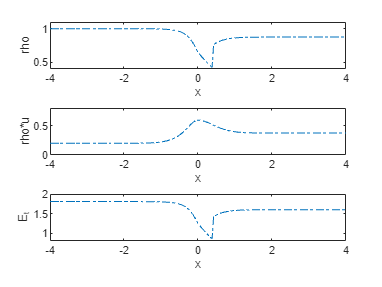


% no of points
np = 200;
dx = (xmax - xmin)/(np-1);
x = xmin:dx:xmax;

% Solution array for (rho, rho*u, E_t)
q=zeros(3,np);
%
% exact solution
%
for i=1:np
   q(:,i) = ExactSolu(x(i), flow);
end

% Plot the conserved variables
subplot(3,1,1);
plot(x,q(1,:),'-.');
xlabel('x');
ylabel('rho');
ylim([0.4,1.1]);
    
subplot(3,1,2);
plot(x,q(2,:),'-.');
xlabel('x');
ylabel('rho*u');
ylim([-0.,0.8]);

subplot(3,1,3);
plot(x,q(3,:),'-.');
xlabel('x');
ylabel('E_t');
ylim([0.8,2.0]);